%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI

% Description:
% This script reads CIR data from a file, calculates the magnitude and phase,
% and visualizes the results. It also calculates phase variance, standard deviation,
% and the ratio of negative phases for each CIR.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear;
clc;

% Read files and extract data
file_paths = {'location(5,3)responder1.txt'};
all_CIR_real_all = {};
all_CIR_imag_all = {};

% Loop through each file and read CIR values
for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end

Total number of read CIR pairs for location(5,3)responder1.txt: 984


disp(['==========================================================================']);         

CIR number 1 for location(5,3)responder1.txt


CIR number 2 for location(5,3)responder1.txt


CIR number 3 for location(5,3)responder1.txt


CIR number 4 for location(5,3)responder1.txt


CIR number 5 for location(5,3)responder1.txt


CIR number 6 for location(5,3)responder1.txt


CIR number 7 for location(5,3)responder1.txt


CIR number 8 for location(5,3)responder1.txt


CIR number 9 for location(5,3)responder1.txt


CIR number 10 for location(5,3)responder1.txt


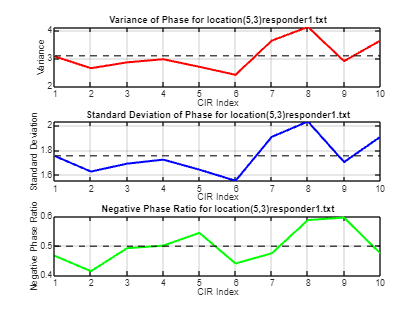


% Initialize vectors for negative phase ratios, variances, and standard deviations
negative_phase_ratios = cell(1, length(file_paths));
varPhase = cell(1, length(file_paths));
stdPhase = cell(1, length(file_paths));

while true
    % Prompt the user for the number of CIRs to display
    prompt = 'Enter the number of CIRs you want to display or 0 to exit: ';
    numCIRs = input(prompt);

    if numCIRs == 0 % Exit if 0 is entered
        break;
    end

    if numCIRs > length(all_CIR_real_all{1})
        disp('The number entered exceeds the available CIR pairs. Please enter a valid number.');
        continue;
    end

    % Process and analyze the CIRs
    for CIRNumber = 1:numCIRs
        for i = 1:length(file_paths)
            file_path = file_paths{i};
            CIR_real_all = all_CIR_real_all{i};
            CIR_imag_all = all_CIR_imag_all{i};

            if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
                disp(['CIR number ', num2str(CIRNumber), ' for ', file_path]);
                disp(['==========================================================================']);

                % Extract real and imaginary values
                CIR_real = CIR_real_all{CIRNumber}(735:850)';
                CIR_imag = CIR_imag_all{CIRNumber}(735:850)';
                
                % Calculate complex values and their metrics
                CIR_complex_values = CIR_real + 1i * CIR_imag;
                CIR_magnitude = abs(CIR_complex_values);
                CIR_phase = angle(CIR_complex_values);

                % Calculate phase variance and standard deviation
                varPhase_value = var(CIR_phase);
                stdPhase_value = std(CIR_phase);
                ratio_negative_phases = sum(CIR_phase < 0) / length(CIR_phase);

                % Store variance and standard deviation values
                if isempty(varPhase{i})
                    varPhase{i} = [];
                end
                if isempty(stdPhase{i})
                    stdPhase{i} = [];
                end
                % Store variance, standard deviation, and negative phase ratio values
                varPhase{i}(CIRNumber) = varPhase_value;
                stdPhase{i}(CIRNumber) = stdPhase_value;
                negative_phase_ratios{i}(CIRNumber) = ratio_negative_phases;

                % Plot magnitudes and phases
                % figure;
                % stem(CIR_magnitude);
                % title(['CIR Magnitude for ', file_path, ' - CIR ', num2str(CIRNumber)]);
                % xlabel('Samples');
                % ylabel('Magnitude');
                % 
                % figure;
                % stem(CIR_phase);
                % title(['CIR Phase for ', file_path, ' - CIR ', num2str(CIRNumber)]);
                % xlabel('Samples');
                % ylabel('Phase (radians)');
            end
            disp('==========================================================================');
        end
    end

    % Convert cell arrays to matrices for final plotting
    for i = 1:length(file_paths)
        if ~isempty(varPhase{i}) && ~isempty(stdPhase{i}) && ~isempty(negative_phase_ratios{i})
            varPhase_matrix = cell2mat(varPhase(i)');
            stdPhase_matrix = cell2mat(stdPhase(i)');
            negative_phase_ratios_matrix = cell2mat(negative_phase_ratios(i)');

            meanVar = mean(varPhase_matrix);
            meanSTD = mean(stdPhase_matrix);
            meanNegativePhaseRatio = mean(negative_phase_ratios_matrix);
            
            % Plot variance, standard deviation, and negative phase ratio for each file
            figure;
            subplot(3, 1, 1);
            plot(varPhase_matrix, 'r', 'LineWidth', 2);
            yline(meanVar, 'black--', 'LineWidth', 1.5);
            title(['Variance of Phase for ', file_paths{i}]);
            xlabel('CIR Index');
            ylabel('Variance');
            grid on;

            subplot(3, 1, 2);
            plot(stdPhase_matrix, 'b', 'LineWidth', 2);
            yline(meanSTD, 'black--', 'LineWidth', 1.5);
            title(['Standard Deviation of Phase for ', file_paths{i}]);
            xlabel('CIR Index');
            ylabel('Standard Deviation');
            grid on;

            subplot(3, 1, 3);
            plot(negative_phase_ratios_matrix, 'g', 'LineWidth', 2);
            yline(meanNegativePhaseRatio, 'black--', 'LineWidth', 1.5);
            title(['Negative Phase Ratio for ', file_paths{i}]);
            xlabel('CIR Index');
            ylabel('Negative Phase Ratio');
            grid on;
        end
    end
end